close all

Consider the 2x2 matrix $\mathbf A$:

A = sym([1, -1; 0 2])

$$A = \left(\begin{array}{cc} 1 & -1\\ 0 & 2 \end{array}\right)$$

- A vector $\mathbf{x}$ is defined through its angle with the $x$-axis below. Adjust the angle $\theta$ so that $\mathbf{x}$ is an eigenvector of $\mathbf{A}$.

- Is there more than one eigenvector of $\mathbf{A}$?

- Based on the values for$\mathbf{A}$ and $\mathbf{Ax}$, what are eigenvalues that correspond to the eigenvectors that you found?

thetad =sym(75);  % In degrees
x = sym([cosd(thetad); sind(thetad)])

$$x = \left(\begin{array}{c} \frac{\sqrt{6}}{4}-\frac{\sqrt{2}}{4}\\ \frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4} \end{array}\right)$$

Ax = sym(A)*x

$$Ax = \left(\begin{array}{c} -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2}+\frac{\sqrt{6}}{2} \end{array}\right)$$

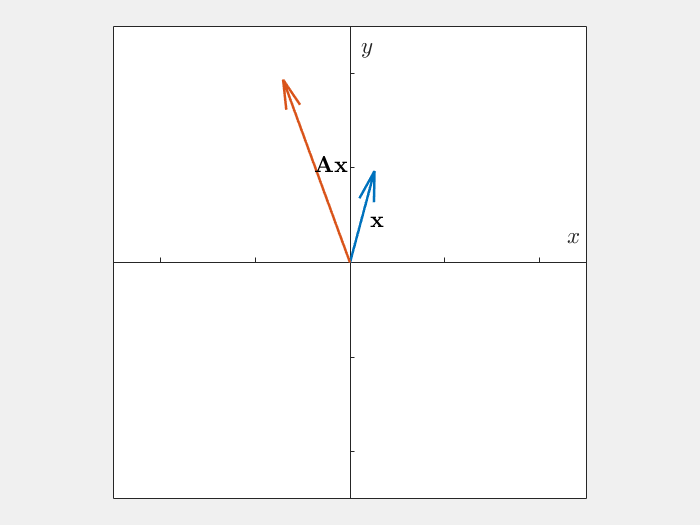

% Plot the vectors
figure('visible','on')
hold on
setup2DVectorPlot([-2.5 2.5 -2.5 2.5])
plotVector2D([0 0],double(x),"\mathbf{x}",-0.5)
plotVector2D([0 0],double(Ax),"\mathbf{Ax}",0.5)
hold off



[V,D] = eig(A)

$$V = \left(\begin{array}{cc} 1 & -1\\ 0 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 1 & 0\\ 0 & 2 \end{array}\right)$$

x = V(:,2);
Ax = sym(A)*x

$$Ax = \left(\begin{array}{c} -2\\ 2 \end{array}\right)$$

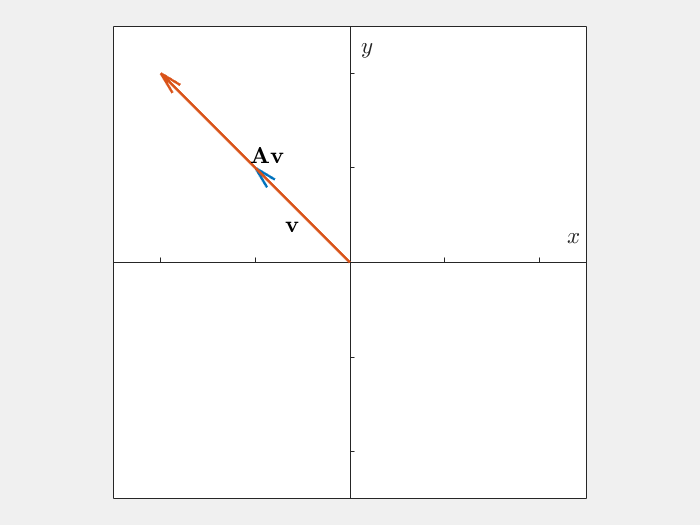

% Plot the vectors
figure('visible','on')
hold on
setup2DVectorPlot([-2.5 2.5 -2.5 2.5])
plotVector2D([0 0],double(x),"\mathbf{v}",-0.5)
plotVector2D([0 0],double(Ax),"\mathbf{Av}",0.5)
hold off

function setup2DVectorPlot(axisLims) 
% Sets up nice axes for visualizing 2D vectors
    fs = 14; % font size for graph
    ax = gca;
    ax.XAxisLocation = "origin";
    ax.YAxisLocation = "origin";    
    ax.Position = [0.05 0.05 0.9 0.9];
    axis equal tight
    axis(axisLims)
    box on
    xlabel("$x$","Interpreter","latex","fontsize",fs)
    ylabel("$y$","Interpreter","latex","fontsize",fs)
    ax.XTick = round(axisLims(1)):round(axisLims(2));
    ax.XTickLabel = [];
    ax.YTick = round(axisLims(1)):round(axisLims(2));
    ax.YTickLabel = [];
end

% Visualizes a 2D vector with the given name
function plotVector2D(u0,u,name,nameOffset) 
    fs = 14; % font size for the graph
    quiver(u0(1),u0(2),u(1),u(2),"autoscale","off","maxheadsize",1/sqrt(dot(u,u)),"linewidth",1.5)
    offset = null(u')/3*nameOffset;
    text(u0(1) + u(1)/2 + offset(1), u0(2) + u(2)/2 + offset(2),strcat("$",name,"$"), ...
        "Interpreter","latex","fontsize",fs,"HorizontalAlignment","center")
end

% Suppress unusued suggestions
%#ok<*IJCL> 
%#ok<*NOPRT>
%#ok<*UNRCH> 